clear; clc;
m = 12;
c = 24;
k = 4800;
omega_n = sym(sqrt(k/m))

$$omega\_n = 20$$

xi = sym(c / (2* sqrt(m*k)))

$$xi = \frac{1}{20}$$

omega_d = sqrt(1-xi^2)*omega_n

$$omega\_d = \sqrt{399}$$

syms t
g = exp(-xi*omega_n*t)/(m*omega_d)*sin(omega_d*t)

$$g = \frac{\sqrt{399}\,{\mathrm{e}}^{-t}\,\sin\left(\sqrt{399}\,t\right)}{4788}$$

F_0 = 100

F_0 = 100

alpha = 1

alpha = 1

f = piecewise(0 < t, F_0*(1-exp(-alpha*t)))

$$f = \left\{ \begin{array}{cl} 100-100\,{\mathrm{e}}^{-t} & \text{ if }0<t \end{array}\right.$$

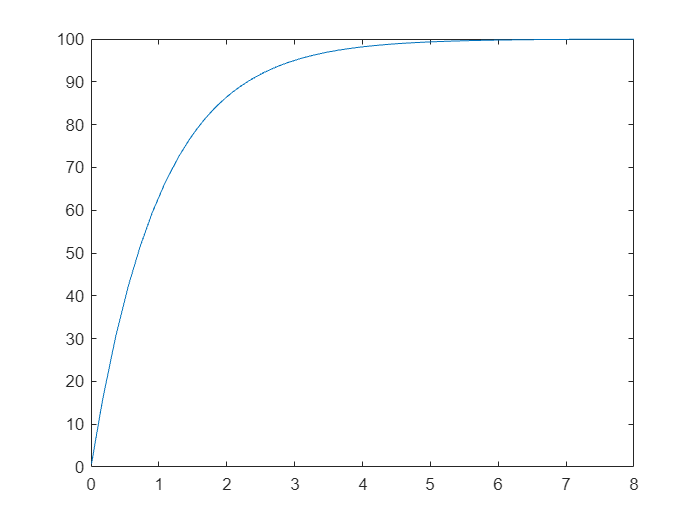

fplot(f, [0, 8*alpha])

syms tau
int_f = subs(f, t, tau) * subs(g, t, t - tau)

$$int\_f = \left\{ \begin{array}{cl} -\frac{\sqrt{399}\,{\mathrm{e}}^{\tau -t}\,\sin\left(\sqrt{399}\,\left(t-\tau \right)\right)\,\left(100\,{\mathrm{e}}^{-\tau }-100\right)}{4788} & \text{ if }0<\tau \end{array}\right.$$

x_precise = int(int_f, tau, 0, t)

$$x\_precise = \left\{ \begin{array}{cl} \frac{25\,{\mathrm{e}}^{-t}\,\left(\cos\left(\sqrt{399}\,t\right)-1\right)}{1197}+\frac{25\,\sqrt{399}\,\left(\frac{\sqrt{399}}{400}-\frac{{\mathrm{e}}^{-t}\,\left(\sin\left(\sqrt{399}\,t\right)+\sqrt{399}\,\cos\left(\sqrt{399}\,t\right)\right)}{400}\right)}{1197} & \text{ if }0<t\\ 0 & \text{ if }t\leq 0 \end{array}\right.$$

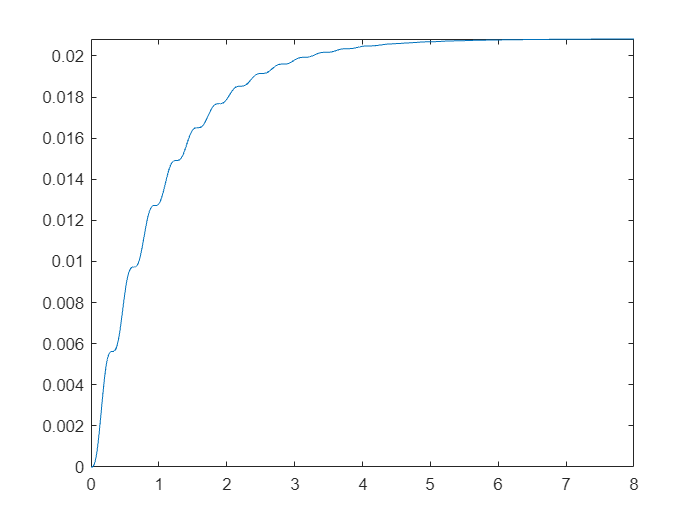

fplot(x_precise, [0, 8*alpha])

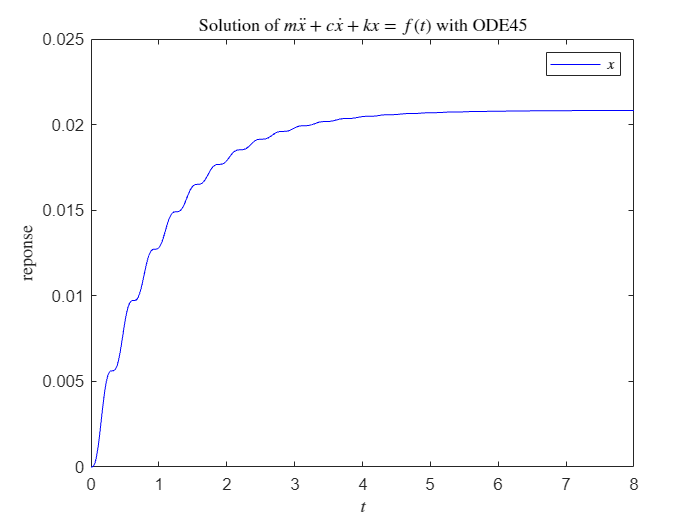

time_span = [0, 8*alpha];
x_init = [
    0; 
    0];
f = @(t) Force(t, F_0, alpha);
[t_span,x_ode] = ode45(@(t, x) vdp1(t, x, f, m, c, k), time_span, x_init);
plot(t_span, x_ode(:,1), '-b')
title('Solution of $m \ddot x + c \dot x + k x = f(t)$ with ODE45', 'Interpreter','Latex');
xlabel('$t$', 'Interpreter','Latex');
ylabel('reponse', 'Interpreter','Latex');
legend('$x$', 'Interpreter','Latex');

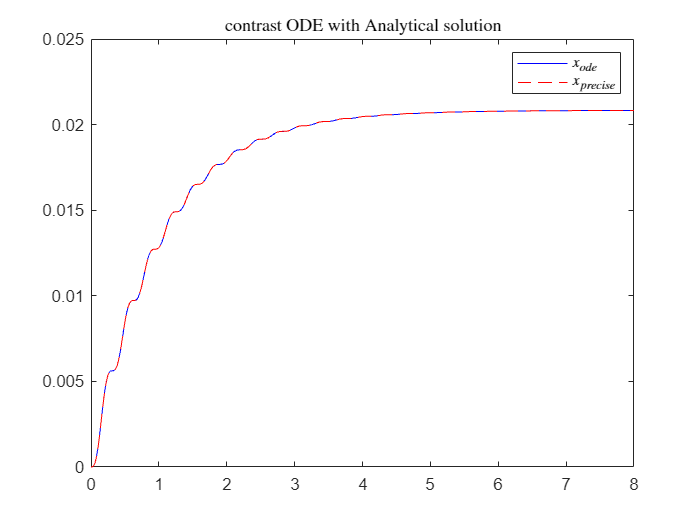

plot(t_span, x_ode(:,1), 'b-', t_span, arrayfun(@(x) double(subs(x_precise, t, x)), t_span), 'r--')
title('contrast ODE with Analytical solution', 'Interpreter','Latex');
legend('$x_{ode}$', '$x_{precise}$', 'Interpreter','Latex');

function dydt = vdp1(t, x, f, m, c, k)
  dydt = [
      x(2); 
      (f(t) - c*x(2) - k*x(1))/m];
end
function f = Force(t, F_0, alpha)
  if 0 < t  
    f = F_0*(1-exp(-alpha*t));
  else
    f = 0;
  end
end